# Clustering

Clustering is a very commonly-used type of analysis in machine learning.  This is a form of **unsupervised learning**: we are looking for some kind of interesting structure in the data which is a set of features.  The word implies that we are looking for "groups" or categories that might exist in the data.  Since we have spent time talking about density estimation, you might think of clustering as locating areas of the feature space that have high density.

The results of clustering can be analysed to understand something about the dataset (what groups exist? what are the most typical/unusual data points, what is their shape and relative distance to each other?).

There are hundereds of clustering algorithms but we will focus on three (rather different) ones:

- $k$-means

- Hierarchical

- Mean shift

## $k$-means Clustering

The $k$-means algorithm is simple: given a dataset $\mathcal{X}$, it positions a set of $k$ cluster centres in the feature space by iterating:

- Initalize cluster centres (e.g. randomly)

- Calculate the "ownership" of points to centres (using some distance metric, find the closest centre to each data point)

- Move the centres to the mean of the points that they own

- Goto 2 (until convergence)

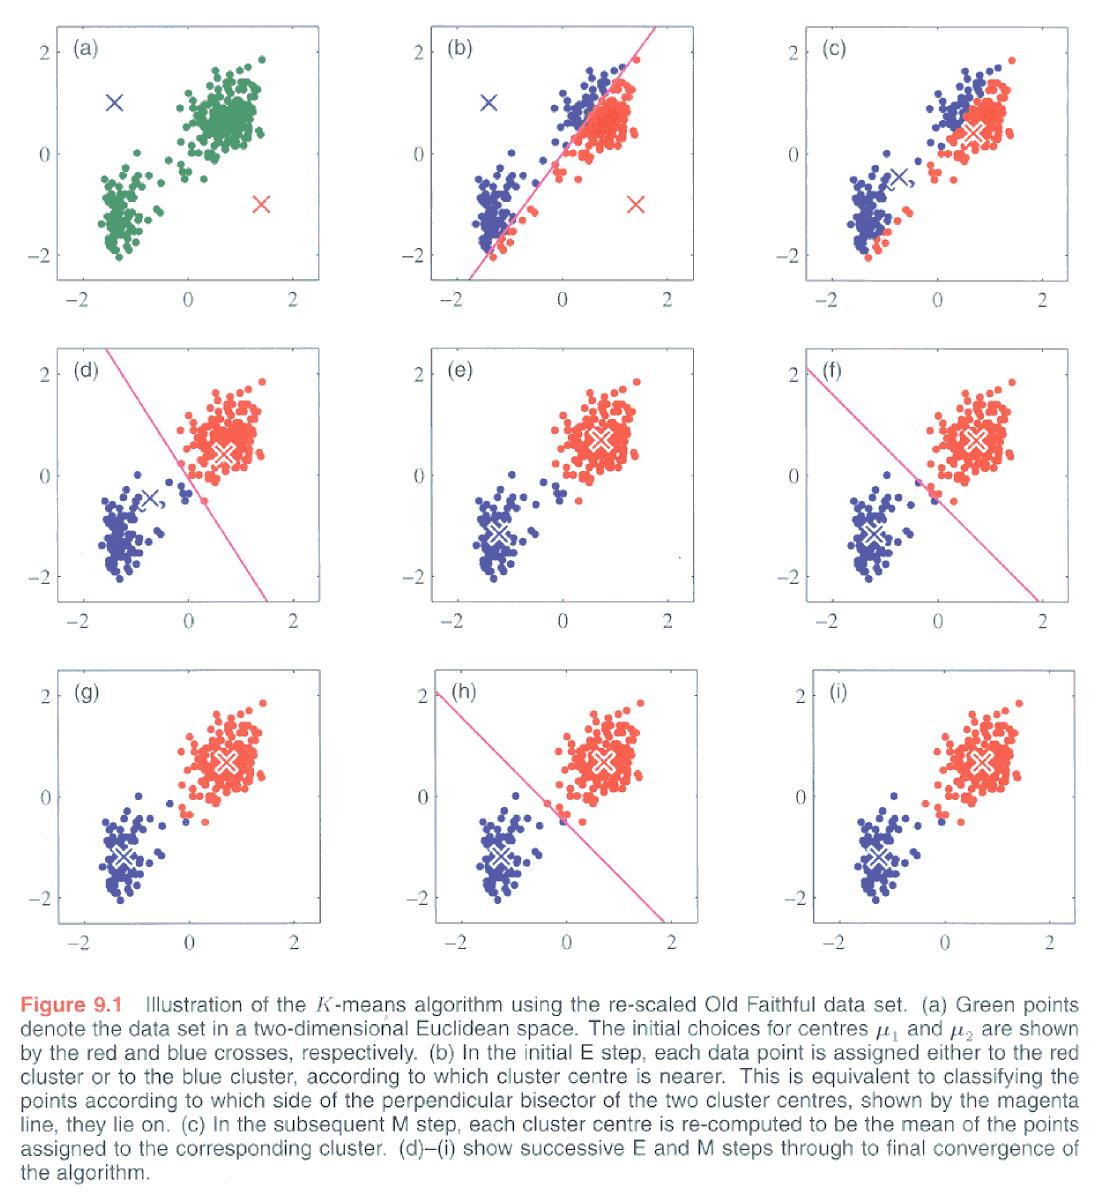

It can be shown that $k$-means performs a local optimization and the objective function is:


$$E(\{\mathbf{m}\}_{i=1}^k |\mathcal{X}) = \sum_t \sum_i b^t_i ||\mathbf{x}^t - \mathbf{m}_i||$$



$$$$
b^t_i = \begin{cases} 1, & \mathrm{if} ||\mathbf{x}^t - \mathbf{m}_i|| = \min_j ||\mathbf{x}^t - \mathbf{m}_j|| \\ 0, & \mathrm{otherwise}
\end{cases}
$$$$


Initialization: the simplest approach is to choose random points from the dataset and position the centres there to start.  Dozens of techniques have been suggested (such as kmeans++):

What might happen with a poor initialisation?

$k$-means always converges to a solution (typically very quickly)

Example (see Alpaydin, Bishop, HTF): colour/image quantization/segmentation

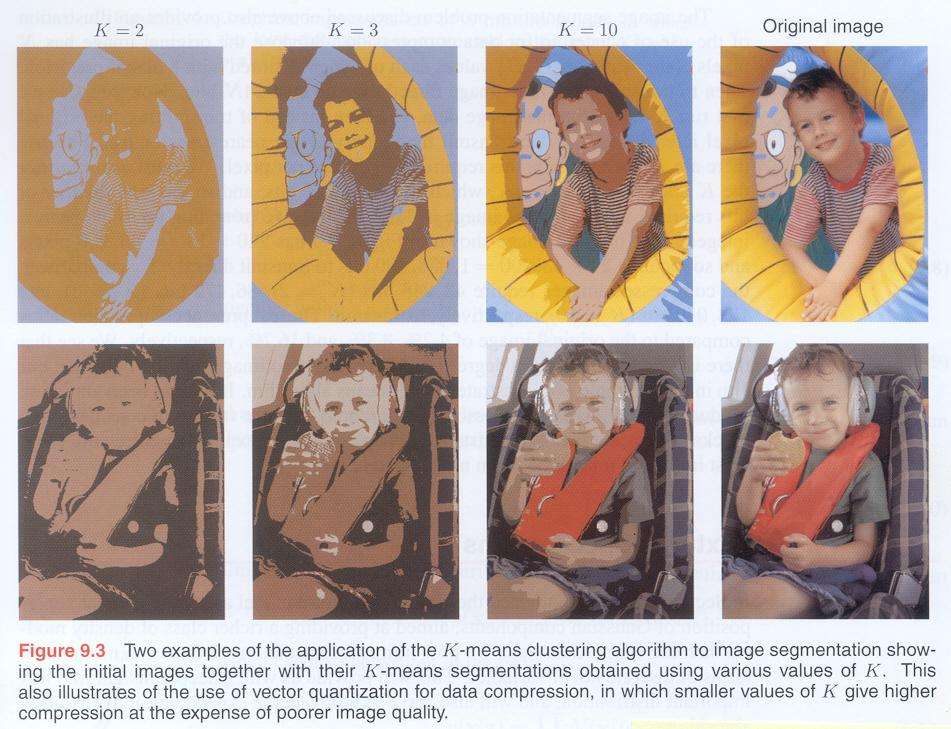

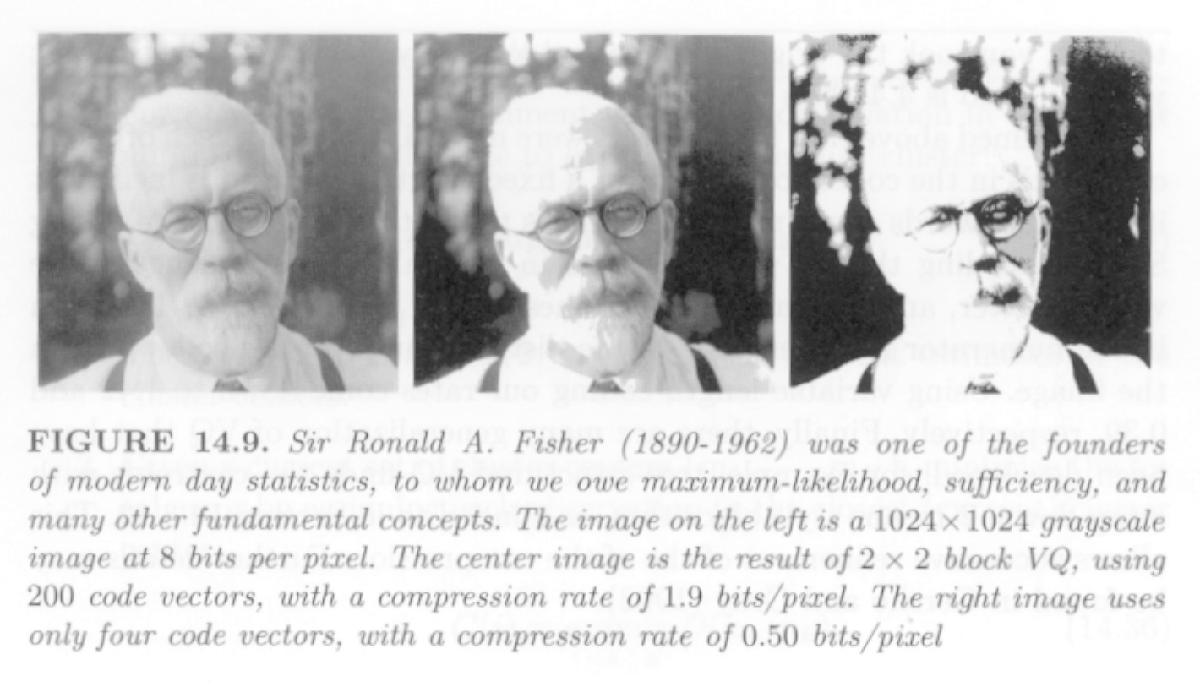

Comparing the steps of $k$-means with the EM algorithm, we can understand $k$-means as a simplified, "hard" version of fitting a mixture of Gaussians with the EM algorithm.

What is the simplification?

A similar algorithm is $k$-medoids, which chooses $k$ of the actual data points as centres rather than mean values.

In operation research, equivalent problems are found in facility location (Weber problem, $p$-median problem).

## Hierarchical Clustering

What is clustering anyway? Analysis of the **distances** between data points!

Different distance metrics can become important here, especially if the data is not continuous.

Take the view that every point is "its own" cluster (i.e. we have $N$ clusters).  Hierarchical clustering makes this the leaves of a tree. Then we construct the tree by merging clustering together (based on distances) until we end up at the root, where we have one cluster (with $N$ points!).

The tree is called a **dendrogram**.

 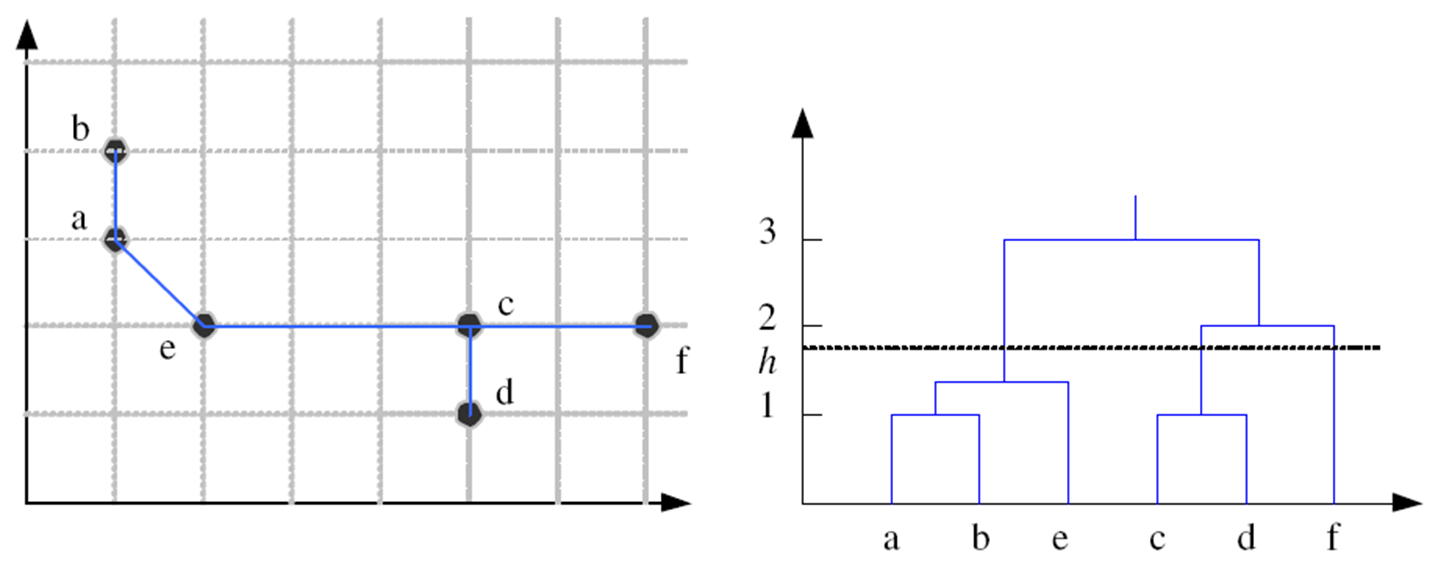

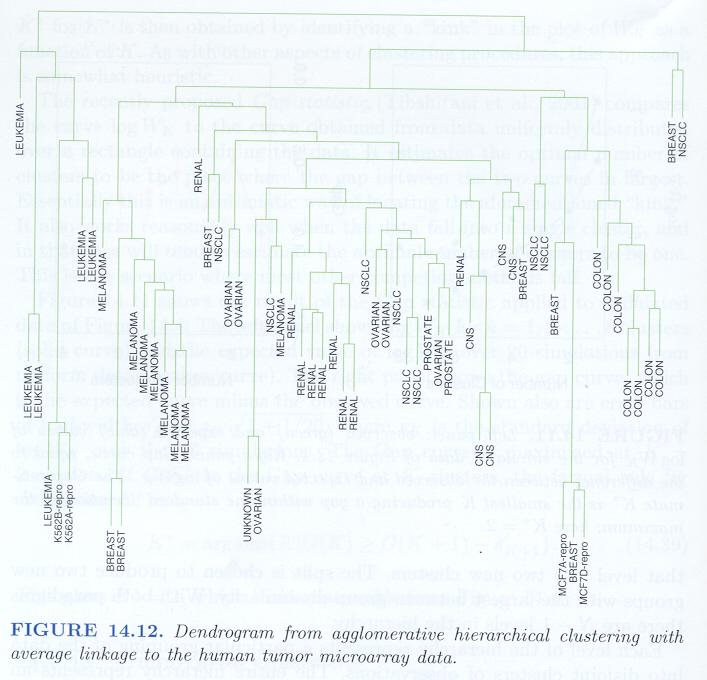

There are different options for deciding when to merge clusters (see, e.g. Alpaydin) which produce different results so the interpretation is somewhat subjective:

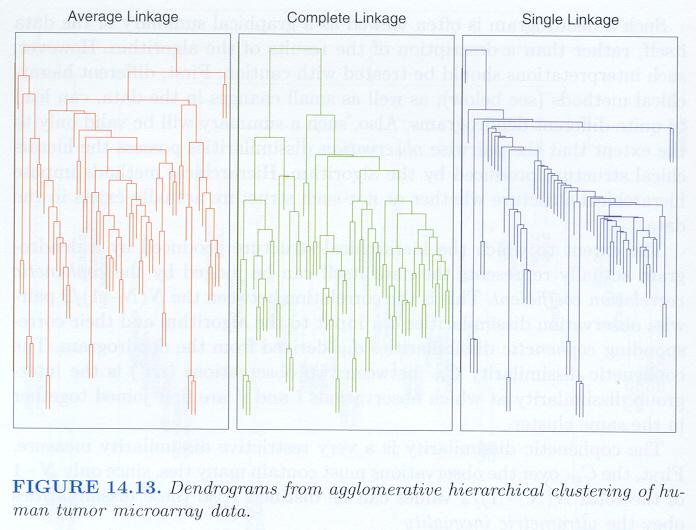

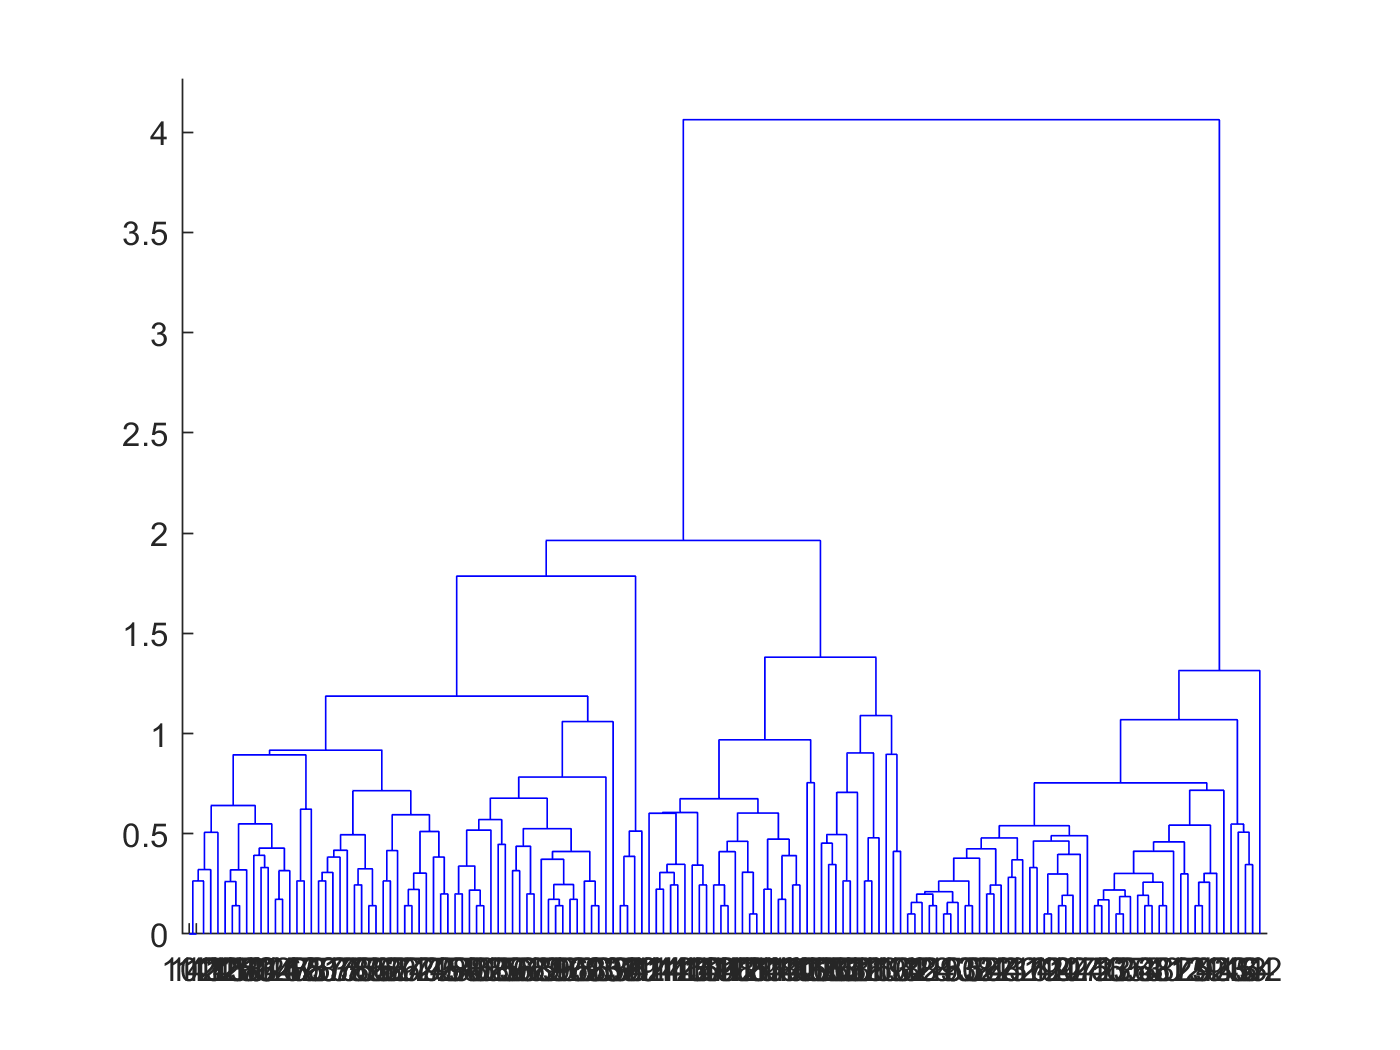

% Dendrograms for the Iris dataset
load fisheriris
tree = linkage(meas,'average');
dendrogram(tree,0)

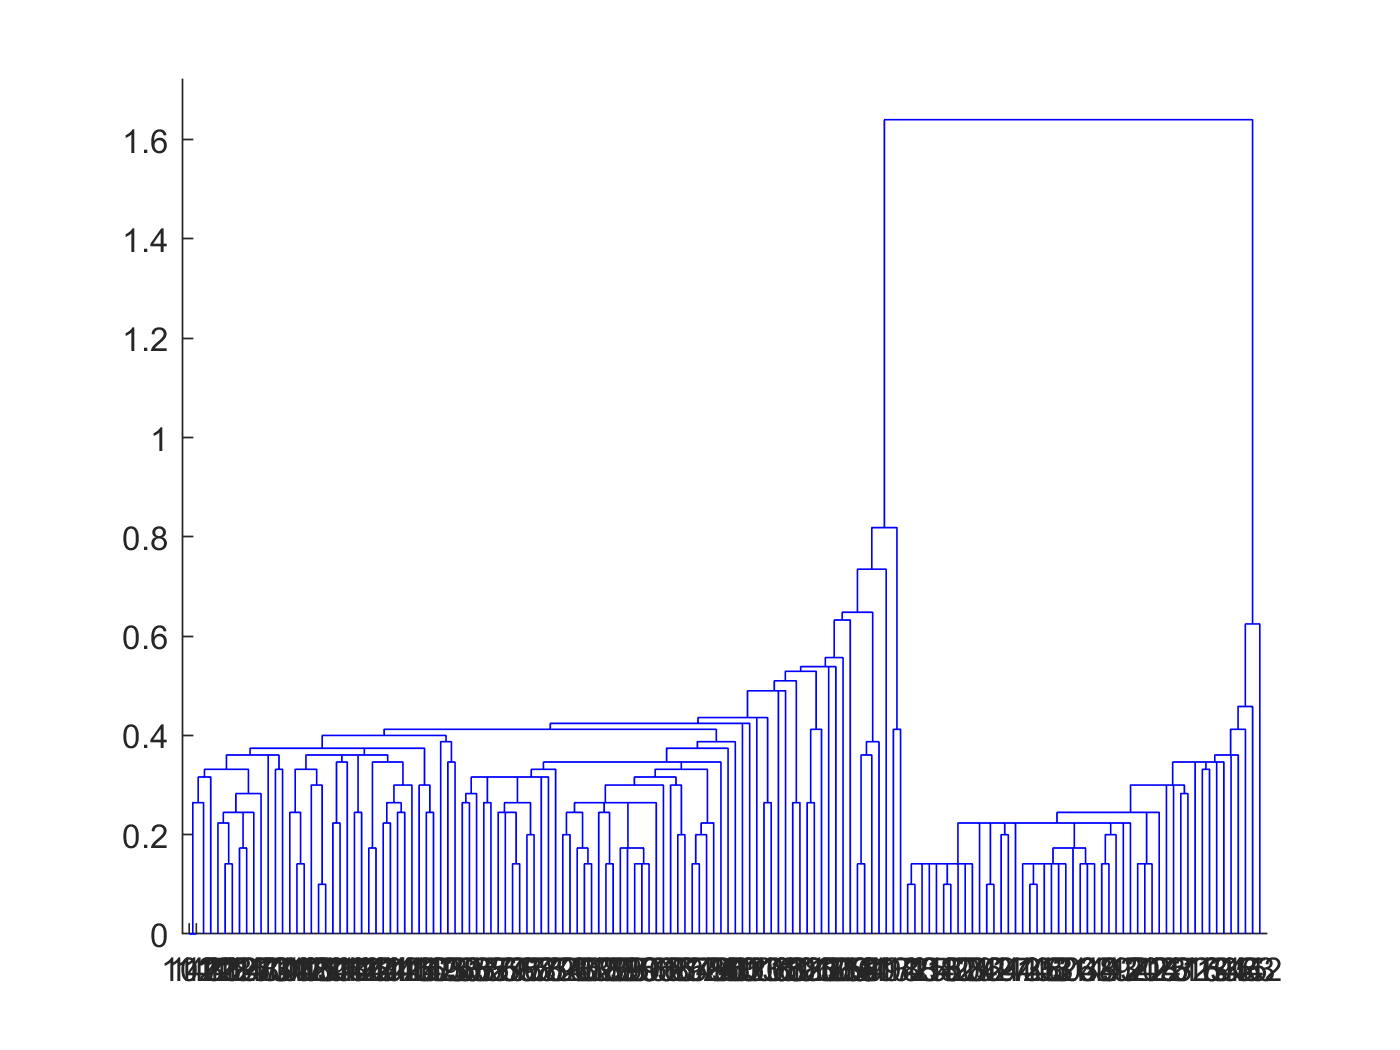

tree = linkage(meas,'single');
dendrogram(tree,0)

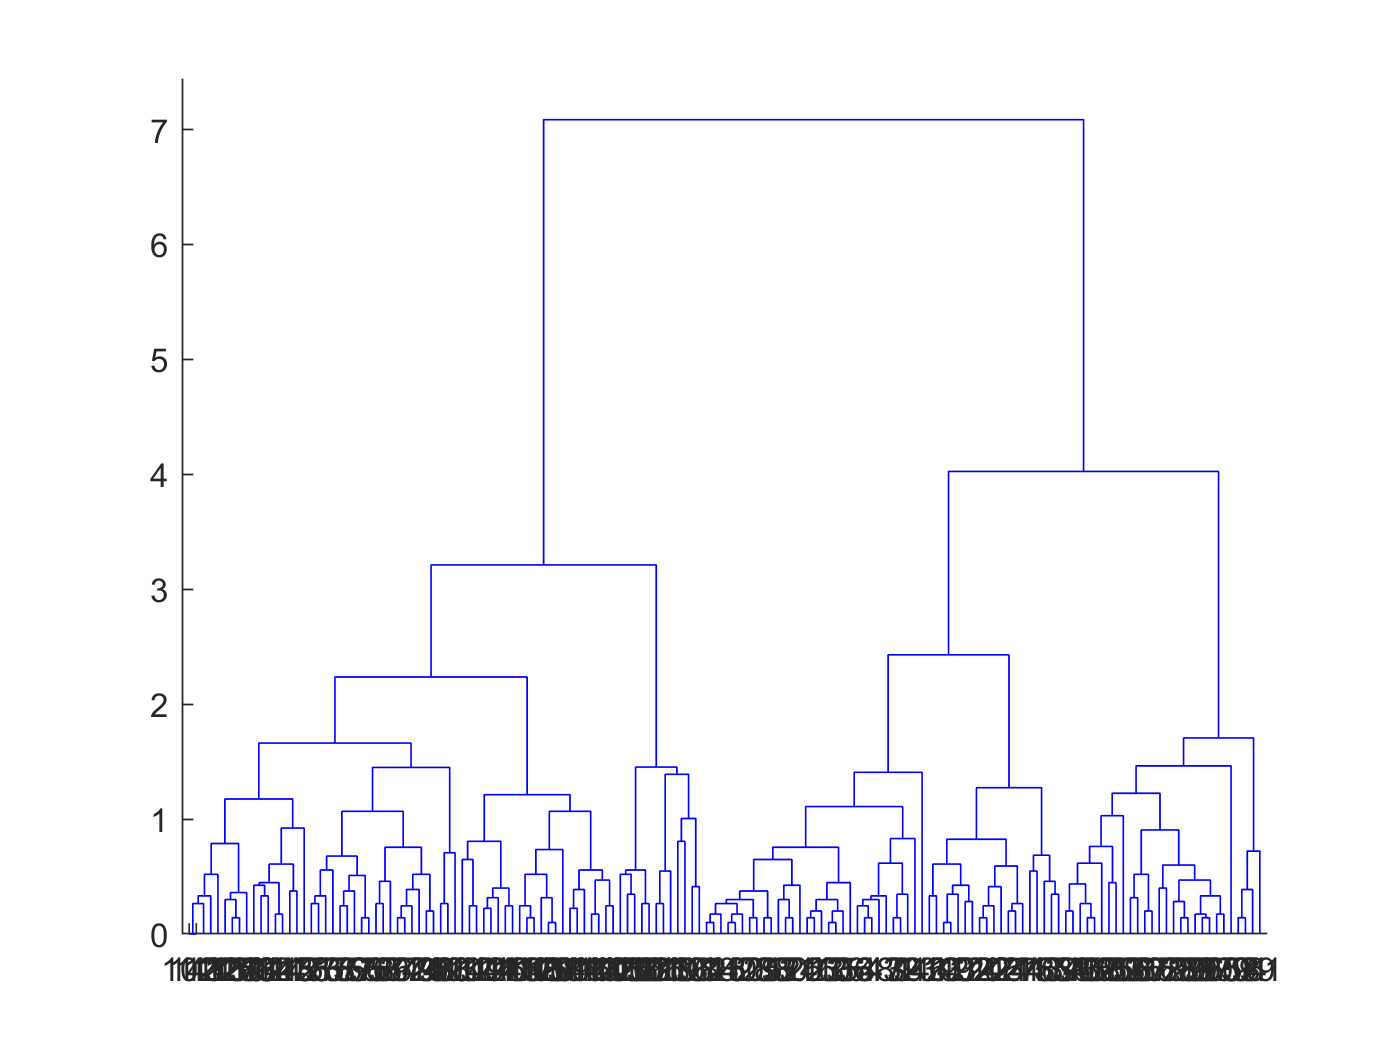

tree = linkage(meas,'complete');
dendrogram(tree,0)

## Mean Shift Clustering

The mean shift clustering algorithm has similarities with non-paramteric methods. We will look at the references in class to get an understanding of how it works.  We will only need the first couple of pages of the paper by Cheng.